Fit, compare, analyze, and plot Experiment 2 behavioural models

projectDir = '/Users/foxxis/Desktop/HBI/exp2';
cd(projectDir);
addpath(projectDir);

addpath(fullfile(projectDir, 'src'));
addpath(fullfile(projectDir, 'src', 'models'));
addpath(fullfile(projectDir, 'src', 'plotting'));
addpath(fullfile(projectDir, 'src', 'r2_assignment'));

Load Experiment 2 data.

data_file = '/Users/foxxis/Documents/social induction/experiment data/exp2/final_data.csv';

raw_tbl = readtable(data_file);
vars = {'p1','p2','p3','p4','p5','p6','p7','p8'};

Y = table2array(raw_tbl(:, vars));
if ~isnumeric(Y)
    Y = str2double(string(Y));
end
N = size(Y, 1);

data = cell(N, 1);
for s = 1:N
    data{s} = struct('y', Y(s,:));
end

Prepare fitting output folder. results/fitting is the output location

fitDir = fullfile(projectDir, 'results', 'fitting');
if exist(fitDir, 'dir') ~= 7
    mkdir(fitDir);
end

outputs = struct();

Model fitting and HBI comparison. 

validate_cbm_data(data);

cbm_root = '/Users/foxxis/Documents/MATLAB/cbm-master';
addpath(genpath(cbm_root));

assert(exist('cbm_lap', 'file') == 2, ...
    'Cannot find cbm_lap. Check cbm_root in BMI_run_exp2.mlx.');

cd results/fitting/

% The variance v controls the scale of the zero-mean Laplace prior on each
% parameter. A value of 6.25 is suggested by the CBM manual, which is 
% large enough to cover a wide range of parameters with no excessive
% penalty. As our model parameters are additionally transformed with exp()
% in the likelihood function, we use log(6.25) ≈ 1.8 to avoid overly
% dispersed initial parameter values. 
% Robustness checks were also run with alternative v values.

v = 1.8; 

% First, we should run cbm_lap, which fits every model to each subject data 
% separately (i.e. in a non-hierarchical fashion).
% Mentalizing model: one free parameter (log_ce)
prior_ment = struct('mean', zeros(1,1), 'variance', v);
cbm_lap(data, @mentalizing_model, prior_ment, 'lap_mentalizing.mat');

cbm_lap                                           14-Sep-2026 19:34:56
Number of samples: 87
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Sub


% Level-0 model: two free parameters (log_ce, log_n)
prior_vt = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @vt_model, prior_vt, 'lap_vt.mat');

cbm_lap                                           14-Sep-2026 19:34:57
Number of samples: 87
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


% Level-1 (diversity weighted) model: three free parameters (log_ce, log_n, log_e)
prior_dw = struct('mean', zeros(3,1), 'variance', v);
cbm_lap(data, @dw_model, prior_dw, 'lap_dw.mat');

cbm_lap                                           14-Sep-2026 19:35:00
Number of samples: 87
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


% Level-1 (knowledge weighted) model: two free parameters (log_ce, log_n)
prior_kw = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @kw_model, prior_kw, 'lap_kw.mat');

cbm_lap                                           14-Sep-2026 19:35:06
Number of samples: 87
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


% Baseline model: zero free parameters (uniform over responses)
prior_base = struct('mean', 0, 'variance', v);
cbm_lap(data, @baseline_model, prior_base, 'lap_baseline.mat');

cbm_lap                                           14-Sep-2026 19:35:09
Number of samples: 87
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Sub


%Conduct hierarchical Bayesian inference using cbm_hbi
models = {@mentalizing_model, @vt_model, @dw_model, @kw_model, @baseline_model};
fcbm_maps = {'lap_mentalizing.mat', 'lap_vt.mat', 'lap_dw.mat', 'lap_kw.mat', 'lap_baseline.mat'};
hbi_file = 'hbi_compare.mat';
cbm_hbi(data, models, fcbm_maps, hbi_file);

cbm_hbi_hbi                                       14-Sep-2026 19:35:10
Running hierarchical bayesian inference (HBI)...

HBI has been initialized according to
	lap_mentalizing.mat [for model 1]
	lap_vt.mat [for model 2]
	lap_dw.mat [for model 3]
	lap_kw.mat [for model 4]
	lap_baseline.mat [for model 5]
 
Number of samples: 87
Number of models: 5
Iteration 01
Iteration 02
	model frequencies (percent)
	model 1: 16.7| model 2: 23.1| model 3: 21.6| model 4: 23.8| model 5: 14.8| 
                                                           dL:   14.67
                                                           dm:   76.19
                                                           dx:    0.40
Iteration 03
	model frequencies (percent)
	model 1: 15.3| model 2: 24.2| model 3: 19.9| model 4: 25.8| model 5: 14.7| 
                                                           dL:    1.13
                                              


%Load the saved file
S = load(hbi_file);
assert(isfield(S, 'cbm'), 'No cbm variable found in %s.', hbi_file);
cbm = S.cbm;
cbm.output

ans = struct with fields:
                     parameters: {5×1 cell}
                 responsibility: [87×5 double]
                     group_mean: {[0.6450]  [2.2183 -0.6057]  [4.9330e-05 1.0064e-04 2.3555e-05]  [1.7872 0.1630]  [-5.7392e-10]}
    group_hierarchical_errorbar: {[0.1821]  [1.0686 0.3180]  [0.1398 0.1398 0.1398]  [0.1029 0.1339]  [0.1380]}
                model_frequency: [0.1086 0.0331 2.6773e-04 0.6453 0.2128]
                exceedance_prob: [0 0 0 1.0000 4.0000e-06]
      protected_exceedance_prob: [NaN NaN NaN NaN NaN]



cbm_frequency = cbm.output.model_frequency %cbm based model frequency calculated by summing each model's responsibility across all participants

cbm_frequency =     0.1086    0.0331    0.0003    0.6453    0.2128


% model frequency calculated by the proportion of participants best fit by each
% model
resp = cbm.output.responsibility;
[~, bestModelPerSubj] = max(resp, [], 2);
modelIDs = 1:5;
counts = histcounts(bestModelPerSubj, 0.5:1:5.5);
proportions = counts / numel(bestModelPerSubj);
modelNames = {'Mentalizing','VT','DW','KW','Baseline'};
freqTable = table(modelIDs(:), modelNames(:), counts(:), proportions(:), ...
    'VariableNames', {'ModelID','ModelName','Count','Proportion'});
disp(freqTable);

    ModelID       ModelName       Count    Proportion
    _______    _______________    _____    __________

       1       {'Mentalizing'}      5       0.057471 
       2       {'VT'         }      1       0.011494 
       3       {'DW'         }      0              0 
       4       {'KW'         }     62        0.71264 
       5       {'Baseline'   }     19        0.21839 




%parameter
group_mean_m = exp(cbm.output.group_mean{1});group_mean_m

group_mean_m = 1.9061

group_mean_mv = exp(cbm.output.group_mean{2});group_mean_mv

group_mean_mv =     9.1920    0.5457


group_mean_dw = exp(cbm.output.group_mean{3});group_mean_dw

group_mean_dw =     1.0000    1.0001    1.0000


group_mean_kw = exp(cbm.output.group_mean{4});group_mean_kw

group_mean_kw =     5.9729    1.1770


group_mean_b = exp(cbm.output.group_mean{5});group_mean_b

group_mean_b = 1.0000

responsibility = cbm.output.exceedance_prob

responsibility =          0         0         0    1.0000    0.0000




% Calculate proected exceedance probabilities by re-running under the (prior) null hypothesis
cbm_hbi_null(data,hbi_file)

cbm_hbi_hbi                                       14-Sep-2026 19:35:28
Running hierarchical bayesian inference (HBI)- null mode...

HBI has been initialized according to
	lap_mentalizing.mat [for model 1]
	lap_vt.mat [for model 2]
	lap_dw.mat [for model 3]
	lap_kw.mat [for model 4]
	lap_baseline.mat [for model 5]
 
Number of samples: 87
Number of models: 5
Iteration 01
Iteration 02
                                                           dL:    6.71
                                                           dx:    0.17
Iteration 03
                                                           dL:    0.10
                                                           dx:    0.05
Iteration 04
                                                           dL:    0.30
                                                           dx:    0.02
Iteration 05
                                                           dL:    0.31
        

ans = struct with fields:
        method: 'hbi'
         input: [1×1 struct]
       profile: [1×1 struct]
          math: [1×1 struct]
        output: [1×1 struct]
    exceedance: [1×1 struct]



% Load the corrected HBI results
S   = load(hbi_file, 'cbm');
cbm = S.cbm;

% Extract posterior quantities (for inspection)
pxp  = cbm.output.protected_exceedance_prob;
pxp

pxp =     0.0000    0.0000    0.0000    1.0000    0.0000


Compute R² metrics

cd(projectDir);
run_exp2_r2_assignment(projectDir, data, cbm);

Individualized assignment uses each participant's maximum-responsibility model.
Group-winning assignment uses model 4 for every participant.
Categorical simulation iteration 1000/10000
Categorical simulation iteration 2000/10000
Categorical simulation iteration 3000/10000
Categorical simulation iteration 4000/10000
Categorical simulation iteration 5000/10000
Categorical simulation iteration 6000/10000
Categorical simulation iteration 7000/10000
Categorical simulation iteration 8000/10000
Categorical simulation iteration 9000/10000
Categorical simulation iteration 10000/10000
    pooled_r2_individualized    pooled_r2_group_winner    pooled_r2_diff    pooled_ci_low    pooled_ci_high    mean_subject_r2_individualized    mean_subject_r2_group_winner    mean_subject_r2_diff    mean_subject_ci_low    mean_subject_ci_high
   

Figures. 

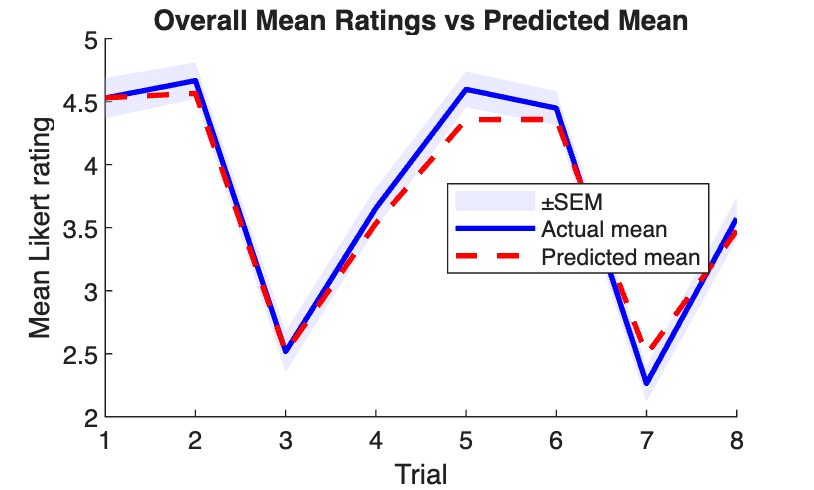

% -------- Generate summary plots --------
% Determine best model per subject again (for plotting)
resp = cbm.output.responsibility;
[~, bestModelPerSubj] = max(resp, [], 2);

% 1) Overall mean ratings vs predicted mean ratings
plot_overall_means(data, cbm, bestModelPerSubj);

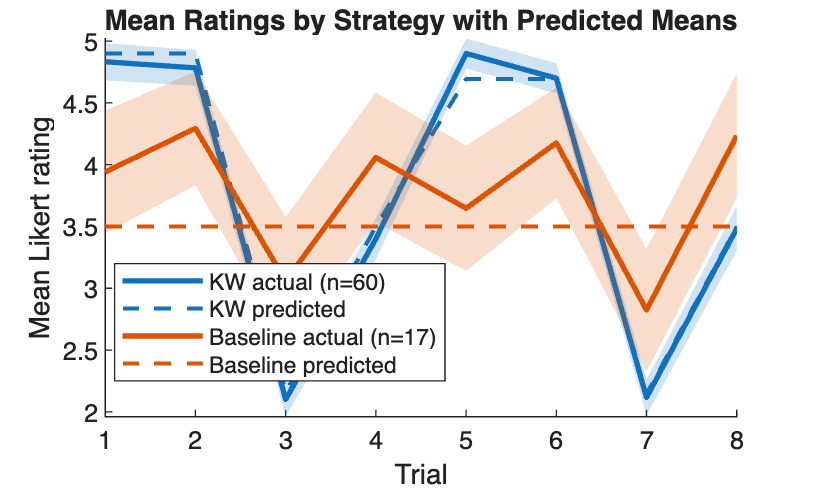


% 2) Mean ratings by strategy group with predicted means
plot_choices_by_strategy(data, cbm, bestModelPerSubj);

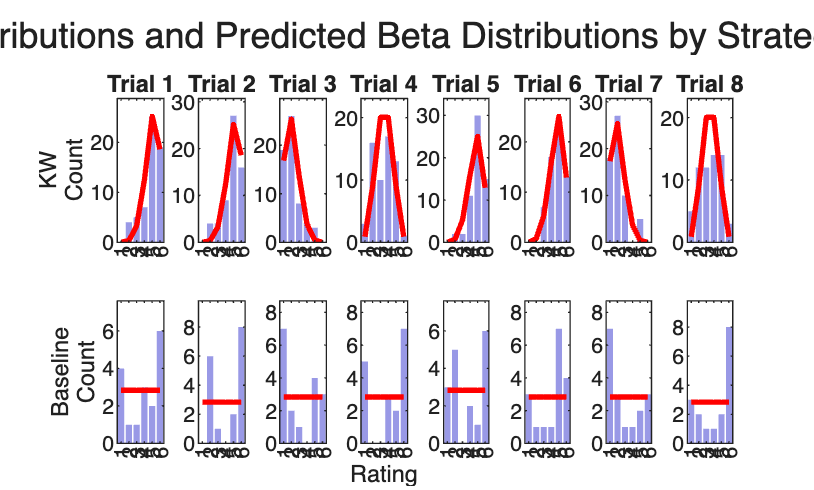


% 3) Distributions of choices by strategy and trial with beta predictions
plot_choice_distribution_beta(data, cbm, bestModelPerSubj);

Robustness Check

cd results/fitting/
v = 3; 

% First, we should run cbm_lap, which fits every model to each subject data 
% separately (i.e. in a non-hierarchical fashion).
% Mentalizing model: one free parameter (log_ce)
prior_ment = struct('mean', zeros(1,1), 'variance', v);
cbm_lap(data, @mentalizing_model, prior_ment, 'lap_mentalizing_r.mat');

cbm_lap                                           14-Sep-2026 19:36:06
Number of samples: 87
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Sub


% Level-0 model: two free parameters (log_ce, log_n)
prior_vt = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @vt_model, prior_vt, 'lap_vt_r.mat');

cbm_lap                                           14-Sep-2026 19:36:08
Number of samples: 87
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


% Level-1 (diversity weighted) model: three free parameters (log_ce, log_n, log_e)
prior_dw = struct('mean', zeros(3,1), 'variance', v);
cbm_lap(data, @dw_model, prior_dw, 'lap_dw_r.mat');

cbm_lap                                           14-Sep-2026 19:36:11
Number of samples: 87
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


% Level-1 (knowledge weighted) model: two free parameters (log_ce, log_n)
prior_kw = struct('mean', zeros(2,1), 'variance', v);
cbm_lap(data, @kw_model, prior_kw, 'lap_kw_r.mat');

cbm_lap                                           14-Sep-2026 19:36:17
Number of samples: 87
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Su


% Baseline model: zero free parameters (uniform over responses)
prior_base = struct('mean', 0, 'variance', v);
cbm_lap(data, @baseline_model, prior_base, 'lap_baseline_r.mat');

cbm_lap                                           14-Sep-2026 19:36:20
Number of samples: 87
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
Subject: 30
Subject: 31
Subject: 32
Subject: 33
Subject: 34
Subject: 35
Subject: 36
Subject: 37
Subject: 38
Subject: 39
Subject: 40
Subject: 41
Subject: 42
Subject: 43
Subject: 44
Subject: 45
Subject: 46
Subject: 47
Subject: 48
Subject: 49
Subject: 50
Subject: 51
Subject: 52
Subject: 53
Subject: 54
Subject: 55
Subject: 56
Subject: 57
Subject: 58
Subject: 59
Sub


%Conduct hierarchical Bayesian inference using cbm_hbi
models = {@mentalizing_model, @vt_model, @dw_model, @kw_model, @baseline_model};
fcbm_maps = {'lap_mentalizing_r.mat', 'lap_vt_r.mat', 'lap_dw_r.mat', 'lap_kw_r.mat', 'lap_baseline_r.mat'};
hbi_file = 'hbi_compare_r.mat';
cbm_hbi(data, models, fcbm_maps, hbi_file);

cbm_hbi_hbi                                       14-Sep-2026 19:36:21
Running hierarchical bayesian inference (HBI)...

HBI has been initialized according to
	lap_mentalizing_r.mat [for model 1]
	lap_vt_r.mat [for model 2]
	lap_dw_r.mat [for model 3]
	lap_kw_r.mat [for model 4]
	lap_baseline_r.mat [for model 5]
 
Number of samples: 87
Number of models: 5
Iteration 01
Iteration 02
	model frequencies (percent)
	model 1: 17.2| model 2: 22.9| model 3: 21.0| model 4: 23.4| model 5: 15.5| 
                                                           dL:   15.81
                                                           dm:   76.63
                                                           dx:    0.40
Iteration 03
	model frequencies (percent)
	model 1: 16.1| model 2: 24.2| model 3: 18.9| model 4: 25.3| model 5: 15.5| 
                                                           dL:    2.28
                                    


%Load the saved file
S = load(hbi_file);
assert(isfield(S, 'cbm'), 'No cbm variable found in %s.', hbi_file);
cbm = S.cbm;
cbm.output

ans = struct with fields:
                     parameters: {5×1 cell}
                 responsibility: [87×5 double]
                     group_mean: {[0.6439]  [2.2512 -0.6183]  [4.8881e-05 1.0013e-04 2.3435e-05]  [1.7813 0.1699]  [-1.6337e-09]}
    group_hierarchical_errorbar: {[0.1817]  [1.0390 0.3107]  [0.1398 0.1398 0.1398]  [0.1027 0.1339]  [0.1737]}
                model_frequency: [0.1088 0.0350 2.6729e-04 0.6439 0.2121]
                exceedance_prob: [0 0 0 1.0000 4.0000e-06]
      protected_exceedance_prob: [NaN NaN NaN NaN NaN]


model_frequency = cbm.output.model_frequency

model_frequency =     0.1088    0.0350    0.0003    0.6439    0.2121


group_mean_m = cbm.output.group_mean{1};group_mean_m

group_mean_m = 0.6439

group_mean_mv = cbm.output.group_mean{2};group_mean_mv

group_mean_mv =     2.2512   -0.6183


group_mean_dw = cbm.output.group_mean{3};group_mean_dw

group_mean_dw = 1.0e-03 *

    0.0489    0.1001    0.0234


group_mean_kw = cbm.output.group_mean{4};group_mean_kw

group_mean_kw =     1.7813    0.1699


group_mean_b = cbm.output.group_mean{5};group_mean_b

group_mean_b = -1.6337e-09

responsibility = cbm.output.exceedance_prob

responsibility =          0         0         0    1.0000    0.0000



% Calculate proected exceedance probabilities by re-running under the (prior) null hypothesis
cbm_hbi_null(data,hbi_file)

cbm_hbi_hbi                                       14-Sep-2026 19:36:40
Running hierarchical bayesian inference (HBI)- null mode...

HBI has been initialized according to
	lap_mentalizing_r.mat [for model 1]
	lap_vt_r.mat [for model 2]
	lap_dw_r.mat [for model 3]
	lap_kw_r.mat [for model 4]
	lap_baseline_r.mat [for model 5]
 
Number of samples: 87
Number of models: 5
Iteration 01
Iteration 02
                                                           dL:    8.95
                                                           dx:    0.16
Iteration 03
                                                           dL:    1.13
                                                           dx:    0.05
Iteration 04
                                                           dL:    0.79
                                                           dx:    0.02
Iteration 05
                                                           dL:    0.5

ans = struct with fields:
        method: 'hbi'
         input: [1×1 struct]
       profile: [1×1 struct]
          math: [1×1 struct]
        output: [1×1 struct]
    exceedance: [1×1 struct]



% Load the corrected HBI results
S   = load(hbi_file, 'cbm');
cbm = S.cbm;

% Extract posterior quantities (for inspection)
pxp  = cbm.output.protected_exceedance_prob;
pxp

pxp =     0.0000    0.0000    0.0000    1.0000    0.0000


Local helper functions

function validate_cbm_data(data)
%VALIDATE_CBM_DATA Basic validation for CBM data cell arrays.

assert(iscell(data) && ~isempty(data), ...
    'Data must be a non-empty cell array of subject structs.');

assert(isstruct(data{1}) && isfield(data{1}, 'y'), ...
    'Each data cell must contain a struct with field y.');

M = numel(data{1}.y);
assert(M == 8, 'Experiment 2 data must contain 8 responses per subject.');

for s = 1:numel(data)
    assert(isstruct(data{s}) && isfield(data{s}, 'y'), ...
        'data{%d} must be a struct with field y.', s);
    assert(numel(data{s}.y) == M, ...
        'Subject %d has %d trials; expected %d.', s, numel(data{s}.y), M);

    y = data{s}.y;
    valid = isnan(y) | (y >= 1 & y <= 6);
    assert(all(valid), ...
        'Subject %d contains responses outside the 1..6 Likert range.', s);
end
end
